# findpeaksOverview

A ideia deste arquivo de teste é apresentar o método de detecção de emissões implementado no **appAnalise**, o qual é baseado na função *built-in* do MATLAB `findpeaks`. Essa função interna do MATLAB, contudo, não é chamada, e sim a sua versão modificada – `matlab.findpeaks` – que faz parte do projeto **SupportPackages**. 

O controle desse processo de detecção é executado por métodos estáticos da classe abstrata `util.Detection. São dois os` métodos de detecção de emissões, ambos aplicando `findpeaks` sobre a informação sumarizada da monitoração, contida em `specData.Data{3}.`

- **Método 1 (FindPeaks):** aplica `findpeaks` na curva de média, ou seja, em `specData.Data{3}(:,2)`.

- **Método 2 (FindPeaks+OCC):** aplica `findpeaks` tanto na curva de média – `specData.Data{3}(:,2) `– quanto na curva de MaxHold – `specData.Data{3}(:,3)`. Neste segundo caso, as frequências centrais das emissões identificadas na curva de MaxHold devem apresentar ocupação média e máxima (considerando o tempo de integração) superiores a *thresholds* definidos.

As emissões detectadas são então armazenadas em `specData.UserData.Emissions` sob a forma de tabela.

## Aspectos gerais

No projeto SupportPackages, na pasta "tests/resources/SpecDataBase", tem alguns arquivos de referência gerados pelo Logger (RFEye), appColeta, CelPlan e Argus (R&S). No presente teste, será lido um arquivo desse pasta que foi gerado pelo appColeta.

testFolder = fullfile(fileparts(fileparts(fileparts(fileparts(which('model.SpecDataBase'))))), 'tests');

% Cria instância da classe model.SpecData, inicialmente vazia.
specData   = model.SpecData.empty;

% Cria instância da classe class.ChannelLib.
channelObj = class.ChannelLib('appAnalise');

## Leitura do arquivo

fileName   = fullfile(testFolder, 'resources', 'SpecDataBase', 'appColeta_240321_T151331_ID1_1.bin');
specData   = read(specData, fileName, 'SingleFile');
specData.UserData(1).reportFlag = false;

% É preciso iniciar a propriedade "UserData", que inicialmente está vazia, de forma
% que possa ser observado o devido registro das emissões ao fluxo.
specData

specData =   SpecData with properties:

        UserData: [1×1 model.UserData]
      callingApp: []
        sortType: 'Receiver+Frequency'
        Receiver: 'ROHDE&SCHWARZ,EB500,101.518/002,V04.90-4072.8710.00'
        MetaData: [1×1 struct]
            Data: {[1×219 datetime]  [2001×219 single]  [2001×3 single]  [2001×219 single]  [2001×219 single]}
             GPS: [1×1 struct]
    RelatedFiles: [1×10 table]
         FileMap: []
          Enable: on


idx = 1;
specData(idx).MetaData

ans = struct with fields:
            DataType: 2
           FreqStart: 88000000
            FreqStop: 108000000
          DataPoints: 2001
          Resolution: 24000
                 VBW: -1
           Threshold: -1
           TraceMode: 'ClearWrite'
    TraceIntegration: -1
            Detector: 'Sample'
           LevelUnit: 'dBµV'
             Antenna: [1×1 struct]
              Others: '{"AttMode":"Auto","DF_MeasTime":1,"DF_SquelchMode":"OFF","DF_SquelchValue":10,"FileFormat":"RFlookBin v.2/2","gpsRevisitTime":1,"gpsType":"Built-in","Preamp":"Off","RevisitTime":0.1,"Task":"EM500_LevelAzimuthTask_HOM_2"}'


## Detecção de emissões

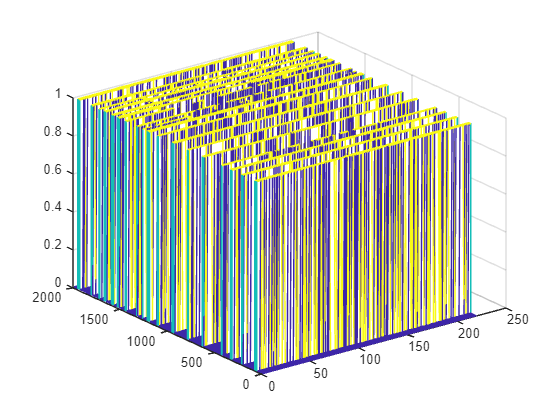

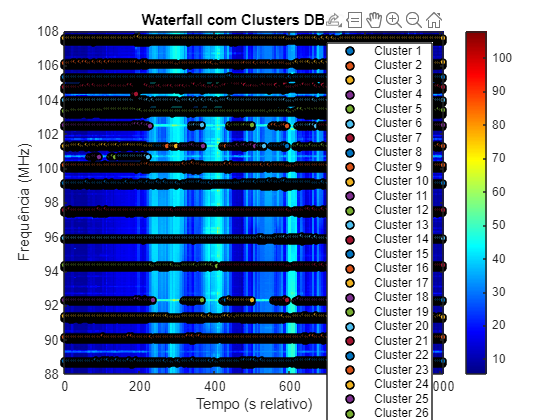

detectionMethod  = "DBSCAN";
minDistance_kHz  = 200; % kHz
minBWPeak_kHz    =  50; % kHz

switch detectionMethod
    case 'FindPeaks'
        detectionFcn = "Média";
        numMaxPeaks  = 100;
        threshold    = -inf;                 % dB
        prominence   = 30; % dB

        Attributes = struct('Algorithm',    detectionMethod, ...
                            'Fcn',          detectionFcn,    ...
                            'NPeaks',       numMaxPeaks,     ...
                            'THR',          threshold,       ...
                            'Prominence',   prominence,      ...
                            'Distance_kHz', minDistance_kHz, ...
                            'BW_kHz',       minBWPeak_kHz);

    case 'FindPeaks+OCC'
        prominence1 = 10; % dB
        prominence2 = 30; % dB
        minMeanOCC  = 10; % Percentual
        minMaxOCC   = 67; % Percentual

        Attributes = struct('Algorithm',    detectionMethod, ...
                            'Distance_kHz', minDistance_kHz, ...
                            'BW_kHz',       minBWPeak_kHz,   ...
                            'Prominence1',  prominence1,     ...
                            'Prominence2',  prominence2,     ...
                            'meanOCC',      minMeanOCC,      ...
                            'maxOCC',       minMaxOCC);
    case 'DBSCAN'
        SNRMin        = 10;
        eps           = [];
        epsFreq_MHz   = 0.2;
        epsTime       = 2;
        MinPts        = 15;
        Showplots     = true;

        Attributes = struct('Algorithm',    detectionMethod, ...
                            'SNRMin',       SNRMin,...
                            'eps',          eps, ...
                            'epsFreq_MHz',  epsFreq_MHz, ...
                            'epsTime',      epsTime, ...
                            'MinPts',       MinPts, ...
                            'Showplots',    Showplots);
end

[newIndex, newFreq, newBW_kHz, Method] = util.Detection.Controller(specData, idx, Attributes);

% Ao atualizar o objeto, armazenando as emissões detectadas em specData.UserData.Emissions,
% o que ocorre por meio de chamada ao método "update" da classe model.SpecDataBase.
% Nesse instante, são realizadas algumas operações para cada emissão, como busca pela
% identificação do canal e do provável emissões.
update(specData(idx), 'UserData:Emissions', 'Add', newIndex, newFreq, newBW_kHz, Method, [], channelObj)

specData(idx).UserData.Emissions

ans = 26×10 table
    idxFrequency    Frequency    BW_kHz    isTruncated    Description    Algorithms     Measures     ChannelAssigned    Classification    auxAppData
    ____________    _________    ______    ___________    ___________    __________    __________    _______________    ______________    __________

          71           88.7       300         true            ""         1×1 struct    1×1 struct      1×1 struct         1×1 struct      1×1 struct
         211           90.1       260         true            ""         1×1 struct    1×1 struct      1×1 struct         1×1 struct      1×1 struct
         331         91.299       300        

jsonencode(specData(idx).UserData.Emissions.Measures(1), "PrettyPrint", true)

ans =     '{
       "Level": {
         "FreqCenter_Min": 54,
         "FreqCenter_Mean": 69.0707779,
         "FreqCenter_Max": 85,
         "Channel_Min": 66.366992192948913,
         "Channel_Mean": 81.851474333916613,
         "Channel_Max": 98.7830572616775
       },
       "FCO": {
         "Channel_Infinite": 100,
         "FreqCenter_Infinite": 100,
         "FreqCenter_Finite_Min": 100,
         "FreqCenter_Finite_Mean": 100,
         "FreqCenter_Finite_Max": 100
       },
       "FBO": {
         "Min": 41.935483870967744,
         "Mean": 84.519074974223017,
         "Max": 100
       },
       "BandWidth": []
     }'


jsonencode(specData(idx).UserData.Emissions.ChannelAssigned(1), "PrettyPrint", true)

ans =     '{
       "autoSuggested": {
         "Frequency": 88.7,
         "ChannelBW": 256
       },
       "userModified": {
         "Frequency": 88.7,
         "ChannelBW": 256
       }
     }'


jsonencode(specData(idx).UserData.Emissions.Classification(1), "PrettyPrint", true)

ans =     '{
       "autoSuggested": {
         "Service": 230,
         "Station": 688884962,
         "Latitude": -13.003889083862305,
         "Longitude": -38.511390686035156,
         "AntennaHeight": 115,
         "Description": "[MOSAICO-SRD] FM-C4, A2, Radio Fm Bahia Sol Ltda (Fistel=50403718961, Estação=688884962), Salvador/BA @ (Latitude=-13.003889º, Longitude=-38.511391º)",
         "Details": "[{\"AntennaAzimuth\":\"330\",\"AntennaElevation\":\".00\",\"AntennaGain\":\"3.23\",\"AntennaPattern\":\"{'0': 0.89, '10': 0.62, '20': 0.26, '30': 0.0, '40': 0.0, '50': 0.0, '60': 0.0, '70': 0.0, '80': 0.0, '90': 0.0, '100': 0.26, '110': 0.62, '120': 0.89, '130': 0.95, '140': 0.92, '150': 0.89, '160': 0.89, '170': 0.89, '180': 0.89, '190': 0.85, '200': 0.82, '210': 0.89, '220': 1.2, '230': 1.62, '240': 1.83, '250': 1.62, '260': 1.2, '270': 0.89, '280': 0.82, '290': 0.85, '300': 0.89, '310': 0.89, '320': 0.89, '330': 0.89, '340': 0.92, '350': 0.95, '5': 0.774, '15': 0.439, '25': 0.107, 

## Plot

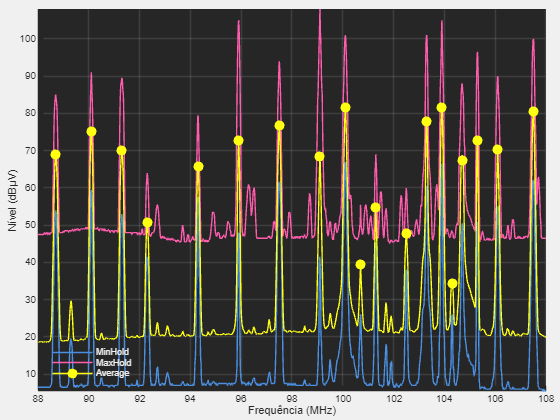

% Identifica índices das emissões detectadas.
idxPeakMax = specData(idx).UserData.Emissions.idxFrequency;
if isempty(idxPeakMax)
    error('Plot será realizado apenas quando identificada ao menos uma emissão.')
end

% Criação de figura e eixo:
f  = uifigure();
ax = uiaxes(f, 'Units', 'normalized', 'Position', [0.01,0.01,.98,.98], ...
               'YGrid', 'on', 'XGrid', 'on', 'GridColor', [.8,.8,.8],  ...
               'Color', [.15,.15,.15], 'FontSize', 10);

% Configuração do eixo:
xData = linspace(specData(idx).MetaData.FreqStart / 1e+6, ... % Hertz >> MHz
                 specData(idx).MetaData.FreqStop  / 1e+6, ...
                 specData(idx).MetaData.DataPoints);

[yDataMin, yDataMax] = bounds(specData(idx).Data{3}, "all");

set(ax, XLim = [xData(1), xData(end)], YLim = [yDataMin, yDataMax])
xlabel(ax, 'Frequência (MHz)')
ylabel(ax, ['Nível (' specData(idx).MetaData.LevelUnit ')'])
legend(ax, 'Location', 'southwest', 'Box', 'off', 'TextColor', [.94,.94,.94])
hold(ax, "on")

% Plot
plot(ax, xData, specData(idx).Data{3}(:,1), 'Color', '#4A90E2', 'DisplayName', 'MinHold');
plot(ax, xData, specData(idx).Data{3}(:,3), 'Color', '#FF5CAD', 'DisplayName', 'MaxHold');
plot(ax, xData, specData(idx).Data{3}(:,2), 'Color', '#ffff12', 'DisplayName', 'Average', 'MarkerIndices', idxPeakMax, 'Marker', 'o', 'MarkerSize', 7, 'MarkerFaceColor', '#ffff12');